# **Virtual Laboratory - Model Predictive Control (MPC) Design for Automatic Vehicle Steering**

**Overview**

This virtual lab contains interactive exercises to study the design of linear and adaptive model predictive controllers (MPCs) for implementing a vehicle steering control system.

**Suggested Prework:**

The following pre-lab activity is recommended to familiarize yourself with MPC concepts: Watch the first 5 videos of the [Understanding Model Predictive Control tech talk series](https://www.mathworks.com/videos/series/understanding-model-predictive-control.html). The videos will help you gain insights into why to use MPC, what it is, how the MPC algorithm (an optimal control algorithm) works, and different variants of MPC control.

**Products:**

MATLAB™, Simulink®, Model Predictive Control Toolbox™, and Automated Driving Toolbox™

Copyright 2023 The MathWorks, Inc.

## Part 1: Model and simulate lateral vehicle dynamics

In this lab, you will design an MPC algorithm to autonomously steer a vehicle. For the vehicle to track a reference trajectory, you need to control its lateral position and yaw angle by adjusting the steering angle. This can be accomplished by building a closed-loop control system as seen in the figure below. You will start with modeling and simulating the lateral vehicle dynamics. 

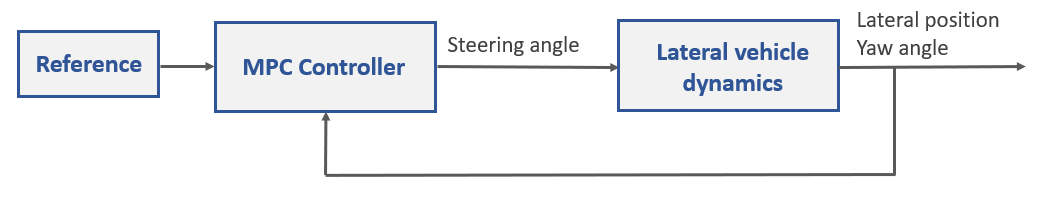

*                                              Closed-loop control system for automatically steering the vehicle using MPC*

The lateral vehicle dynamics are depicted in the below picture. It's described using a bicycle model with two degrees of freedom, lateral position and yaw angle. 

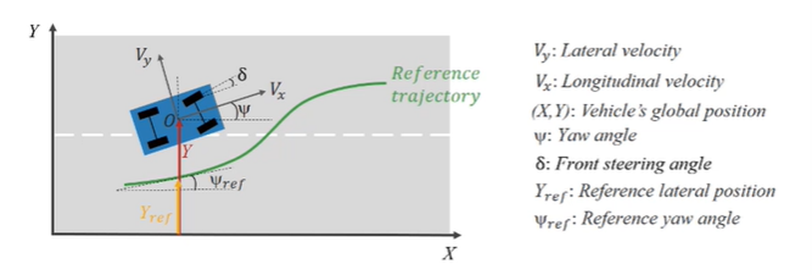

Here,

- $X$ and $Y$ denote the position of the vehicle in global coordinates

- $V_x$ and $V_y$ denote the longitudinal and lateral velocities of the vehicle in body-fixed coordinates with respect to the center of gravity 

- $\psi$ is the yaw angle of the vehicle

- $\delta$ is the front steering angle

- $Y_{\textrm{ref}}$ is the reference lateral position

- $\psi_{\textrm{ref}}$ is the reference yaw angle

Next, you will model the lateral vehicle dynamics which are separated from the longitudinal vehicle dynamics. Therefore, you will assume a constant longitudinal velocity, which you will define below.

**Task 1. **Create a state-space model of the lateral vehicle dynamics. Complete the missing pieces in the below code to specify the values for longitudinal velocity, and state-space matrices. Once complete, click the **Set parameters** and then the **Define Dynamics **buttons to set parameter values and create the state-space model of the lateral vehicle dynamics, *vehicle*.

 
m = 1575;   % Total vehicle mass (kg)
Iz = 2875;  % Yaw moment of inertia of the vehicle (mNs^2)
lf = 1.2;   % Longitudinal distance from the center of gravity to the front tires (m)
lr = 1.6;   % Longitudinal distance from center of gravity to the rear tires (m)
Cf = 19000; % Cornering stiffness of the front tires (N/rad)
Cr = 33000; % Cornering stiffness of the rear tires (N/rad)

% Uncomment the below code and set the longitudinal velocity to a constant value of 15 m/s 
% Vx = 

The model States, Inputs, and Outputs variables are defined as follows:

- State variables: Lateral velocity $V_y$, yaw angle $\psi$, yaw angle rate $r$, global $Y$ position

- Input variable: Front steering angle $\delta$

- Output variable: Global $Y$ position and yaw angle $\psi$

$\[
  A =
  \left[ {\begin{array}{cc}
-\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0& 1 & 0 \\
     -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     1 & Vx & 0 & 0 \\
  \end{array} } \right]
\]$,    $\[
B = 
\left[ {\begin{array}{cc}
\frac{2C_f}{m} \\ 0 \\ \frac{2C_fl_f}{I_z} \\ 0
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
0 & 0 & 0 & 1 \\
0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$

 
% Uncomment the below code and specify the state-space matrices A, B, C and
% D shown above. Create a state-space model (vehicle) of the lateral
% vehicle dynamics using the specified matrices.
% A = 
% B = 
% C = 
% D =
% vehicle = ss(A,B,C,D);

**Task 2. **Simulate the open loop response of the lateral vehicle dynamics model that you created in Task 1 in Simulink. Open the Simulink model: [Linear_MPC_design.slx](matlab:open('./models\Linear_MPC_design.slx')) and follow the steps listed below to complete the missing pieces of the model and obtain the Simulink diagram shown below. 

The model simulates a step input to the steering angle of pi/6 radians, or 30 degrees, which is the maximum steering angle. For a successful (single) lane change maneuver, in this problem the lateral position of the vehicle needs to change from 0 to 4 meters. We will call this the maneuver time, which will inform the choice of MPC Design Parameters like the sample time and prediction horizon that you will specify in the later tasks.

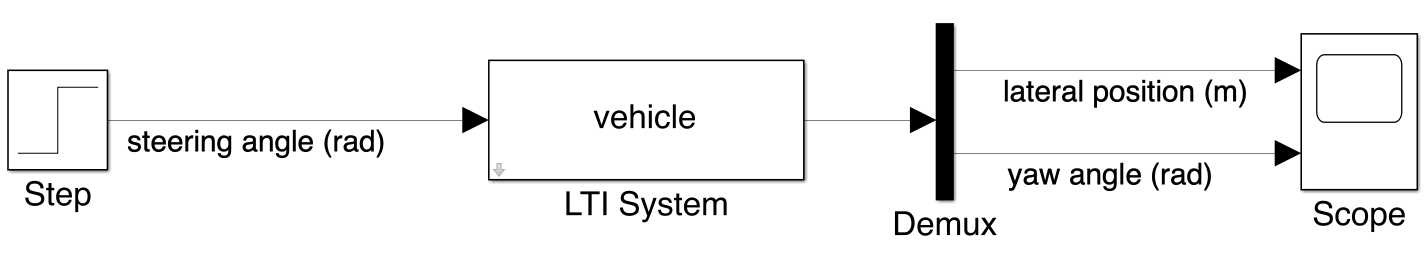

 **Pro-tip**: Double-click anywhere on the Simulink canvas and type the name of the block you want to add.

To complete and simulate the model:

- Add an [LTI System](https://www.mathworks.com/help/control/ref/ltisystem.html?searchHighlight=lti%20block&s_tid=srchtitle_lti%20block_1) block to the model and specify the previously created state-space model, **vehicle**, in the block dialog. Then, connect the block input and output so that the Simulink model matches the diagram shown above. The [Step](https://www.mathworks.com/help/simulink/slref/step.html?searchHighlight=step&s_tid=srchtitle_step_3) and [Scope](https://www.mathworks.com/help/simulink/slref/scope.html?searchHighlight=scope&s_tid=srchtitle_scope_1) blocks provided in the model generate a steering angle input of 30 degrees for the vehicle model and let you view simulation results, respectively. 

- In the Simulink model, click  to run the simulation and insert a snapshot of results shown in Scope. 

              [Insert snapshot here]

- The Scope is configured to log the simulated outputs of the vehicle model, the lateral position and yaw angle, to the MATLAB workspace. To visualize a driving scenario with the logged simulation outputs, run the **simulateScenario** function by pressing the button below. Check out the [Driving Scenario Designer](https://www.mathworks.com/help/driving/ref/drivingscenariodesigner-app.html?searchHighlight=driving%20scenario%20designer&s_tid=srchtitle_driving%20scenario%20designer_1) to learn about driving scenario generation and simulation. (Note: Automated Driving Toolbox is Required for simulating the generated scenario)

- To start the simulation, press the **Play** button in the bottom left-hand side of the figure.

 
YRef = out.simout.signals(1).values;
XRef = out.simout.time*Vx;
waypoints = [XRef YRef zeros(length(YRef),1)];
simulationTime = 10;
simulateScenario(simulationTime,waypoints,Vx,150);

**What do you observe in the simulation results about the open-loop response? What is the maneuver time?**

% task2 = ""

## Part 2: Design a linear MPC controller for the vehicle steering control system

In this section, you will first generate a reference trajectory for the vehicle steering control system, a step-change in lateral position. This reference trajectory will become an input to the MPC controller (see here) that you will design for the lane changing maneuver. You will then learn how to tune the MPC design parameters such as prediction and control horizons, weights, and constraints to improve MPC controller's performance. It’s important to understand that perfect reference tracking is not possible in many scenarios, but model predictive control will result in optimal control based on the parameters of the controller.

**Task 3. **In this task you will model the closed-loop system with the MPC controller by completing the next steps:

- Click the **Load reference trajectory **button to run the code below and load the pre-defined reference values for the lateral position and yaw angle into the MATLAB workspace. 

 
load('reference.mat')

- Import the reference trajectory, **reference**, into the Simulink model using the [From Workspace](https://www.mathworks.com/help/simulink/slref/fromworkspace.html?searchHighlight=from%20workspace&s_tid=srchtitle_from%20workspace_1) block.

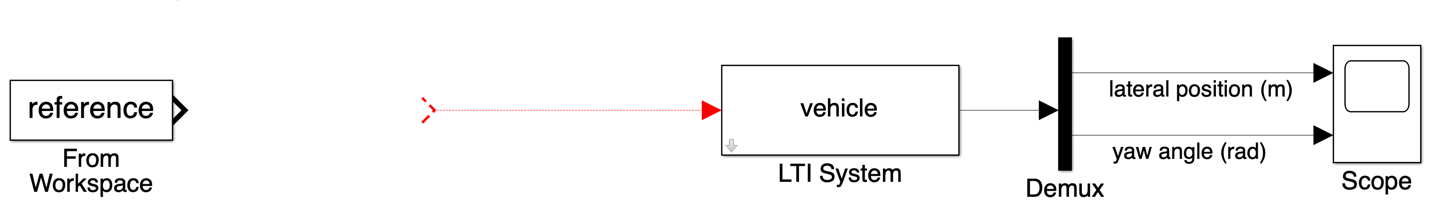

**Note:** Since you'll be using a new reference for the closed-loop system, the [Step](https://www.mathworks.com/help/simulink/slref/step.html?searchHighlight=step&s_tid=srchtitle_step_3) block is not needed in the rest of the simulation. Use the **Debug **tab or **Right Click** on block to comment/uncomment.

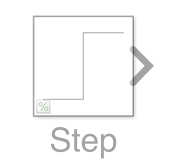

- Add the [MPC Controller](https://www.mathworks.com/help/mpc/ref/mpccontroller.html) block to your model and open up the block dialog to uncheck measured disturbance since this example assumes no measured disturbances. 

- Connect the controller output, *mv,* to the **vehicle** and the *model output* to the input port of the controller (*mo*, measured outputs) as shown below:

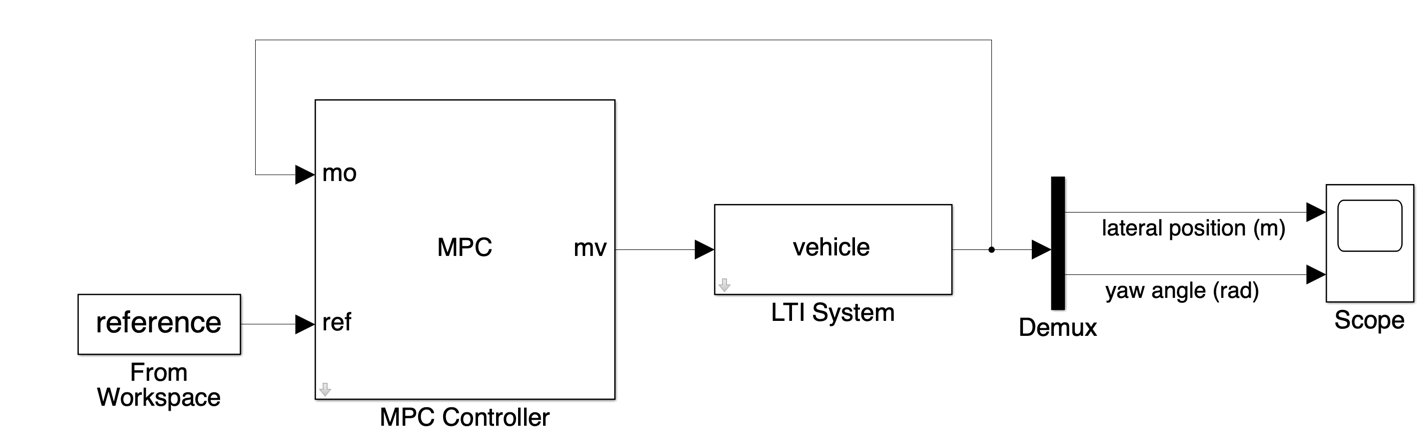

- Log reference and output signals for viewing in the [Simulation Data Inspector](https://www.mathworks.com/help/simulink/slref/simulationdatainspector.html). This tool will be used to visualize reference tracking of the controller. To do this, right click on each signal for logging then select "Log Selected Signals" from the menu. Rename these signal in order to identify them in the **Simulink Data Inspector.** When you are finished the model will have symbols and names on the signals that will be logged as shown below:

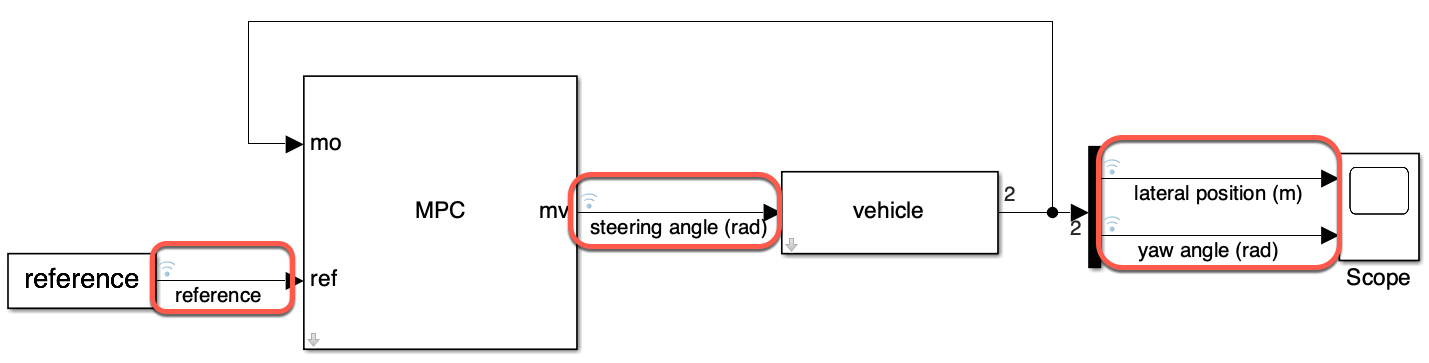

**Task 4. **In this task, you will design an MPC controller with the default values using the [MPC Designer App](https://www.mathworks.com/help/mpc/ref/mpcdesigner-app.html). The app lets you interactively design and simulate MPCs and validate their performance using simulation scenarios. The default MPC is automatically created based on the plant and variables selected with the default values below:

- Prediction Horizon of 10

- Control Horizon of 2

To open MPC Designer App from the MPC Controller block:

- Double-click MPC block, select **Design.**

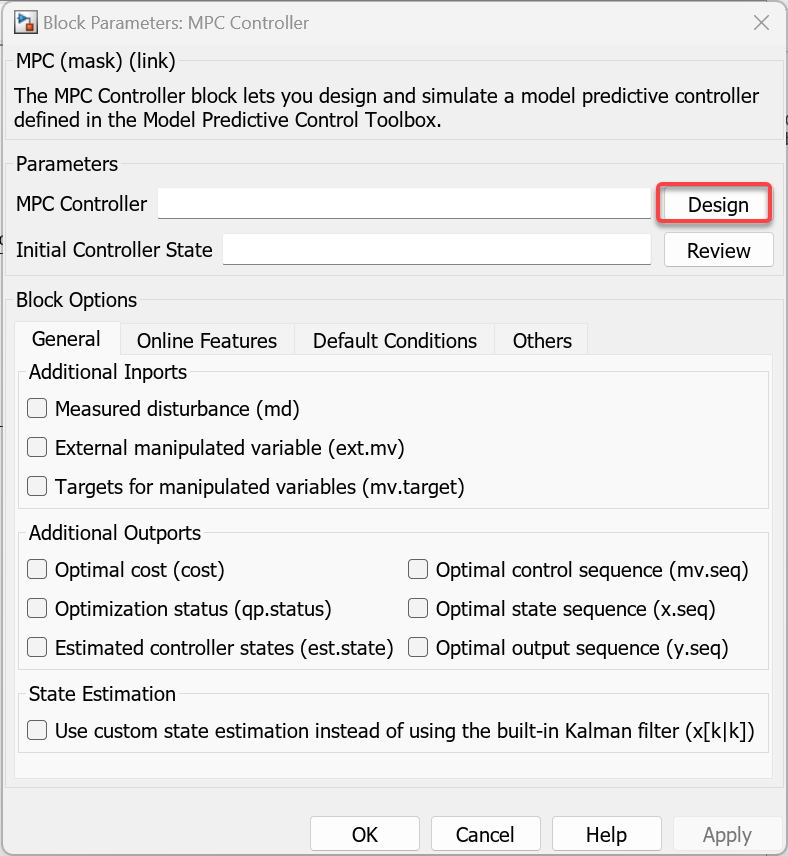

Once the MPC Designer App opens, it is time to define the controller:

- Select MPC Structure from the toolstrip.

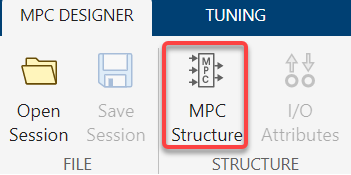

- The first step in defining the structure for the controller is to change the input and output sizes, by clicking the **Change I/O Sizes** button.

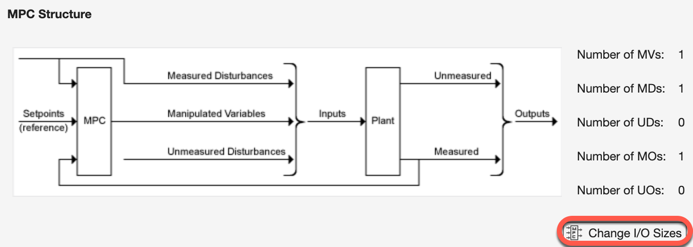

- Since the system has 2 measured outputs, change the value in the dialogue to 2 and select **OK**.

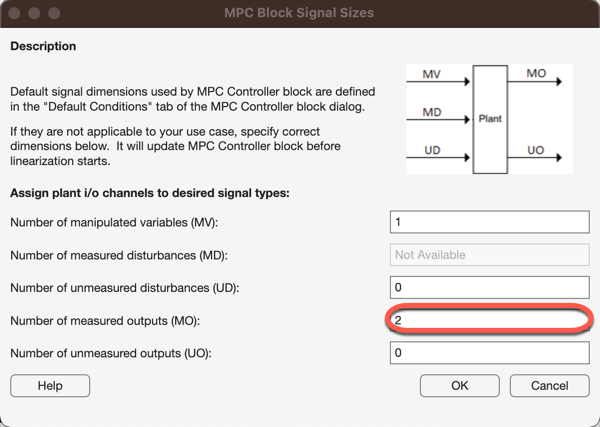

- The MPC Designer App will automatically include plant input and output signals to use as the Manipulated Variables (MV) and Measured Outputs (MO). In this case, your MV is the steering angle of the vehicle, and your MOs are the lateral position and yaw angle of the vehicle. You will need to select them from the list as shown below.

- The sample time, or *Ts,* is recommended to be between 10% and 25% of the maneuver time. A smaller Ts means better disturbance rejection but higher computational load. Return to **Task 2 **to get the approximated maneuver time of the system. If you completed the task successfully then a Sample Time of 0.1 sec should be in the recommended window. Once these options have been selected, press **Import.**

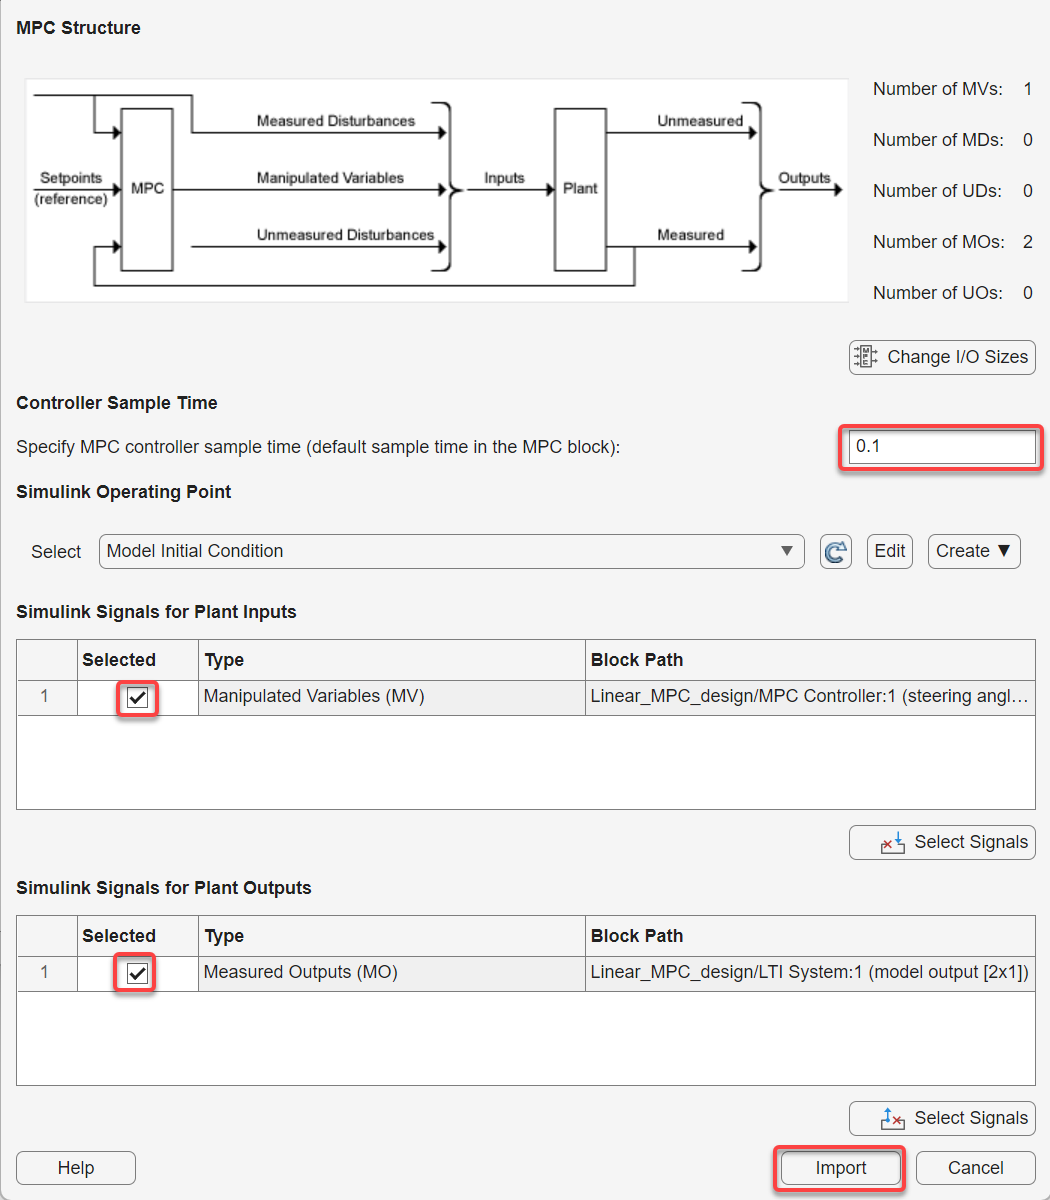

- To prevent confusion around the input and output signals' names and units, update them in the **I/O Attributes**, which you can access from the toolstrip. Update the names and units for the I/O.

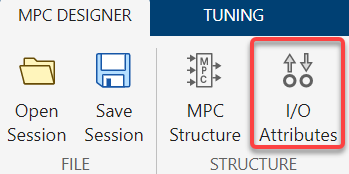

- Here, you can also update the **Scale Factor** for the I/O. This is useful especially when variables have different orders of magnitude. In this case, you need to update the Scale Factor for the yaw angle since it is an order of magnitude below the lateral position output. (Look at scope output for task 2). When done, select** OK.**

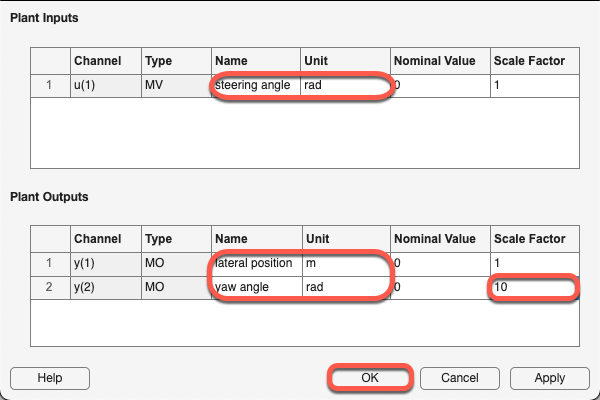

Another important step in MPC Controller analysis is to use a scenario that more closely represents the system you are trying to control. 

- To do this, Select **Edit Scenario > scenario1** from the toolstrip.

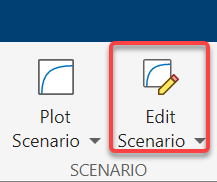

- Modify Signal Types before selecting **OK.**

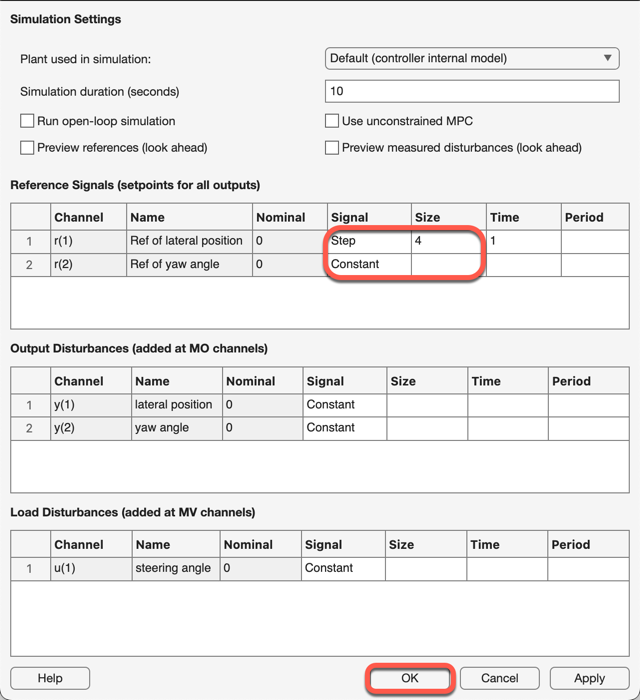

- You will now see the output responses in the MPC Designer App on the right panel. Insert a snapshot of the output responses below:

{Insert here}

- Now that you have created a default MPC Controller, it is time to export the controller, this will create the MPC object in the workspace and assign it to the MPC block before running the simulation.

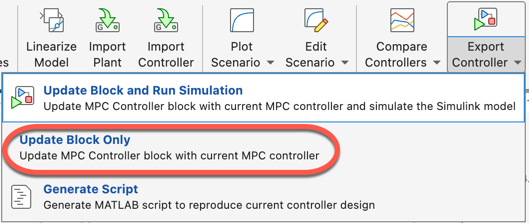

**What is your observation about the performance of the default MPC that you designed above? Comment on the reference tracking of both lateral position and yaw angle.**

% task4 = ""

**Task 5.** Run the Simulink model with the exported controller by pressing  Play in the Simulink toolstrip. The following code lets you visualize the driving scenario.

 
waypoints = [out.simout.time*Vx out.simout.signals(1).values zeros(length(out.simout.signals(1).values),1)];
simulateScenario(simulationTime,waypoints,Vx,150);

In the Simulink toolstrip, select the **Data Inspector** from Simulation > Review Results. In the Data Inspector, select the following layout to separate the reference variables:

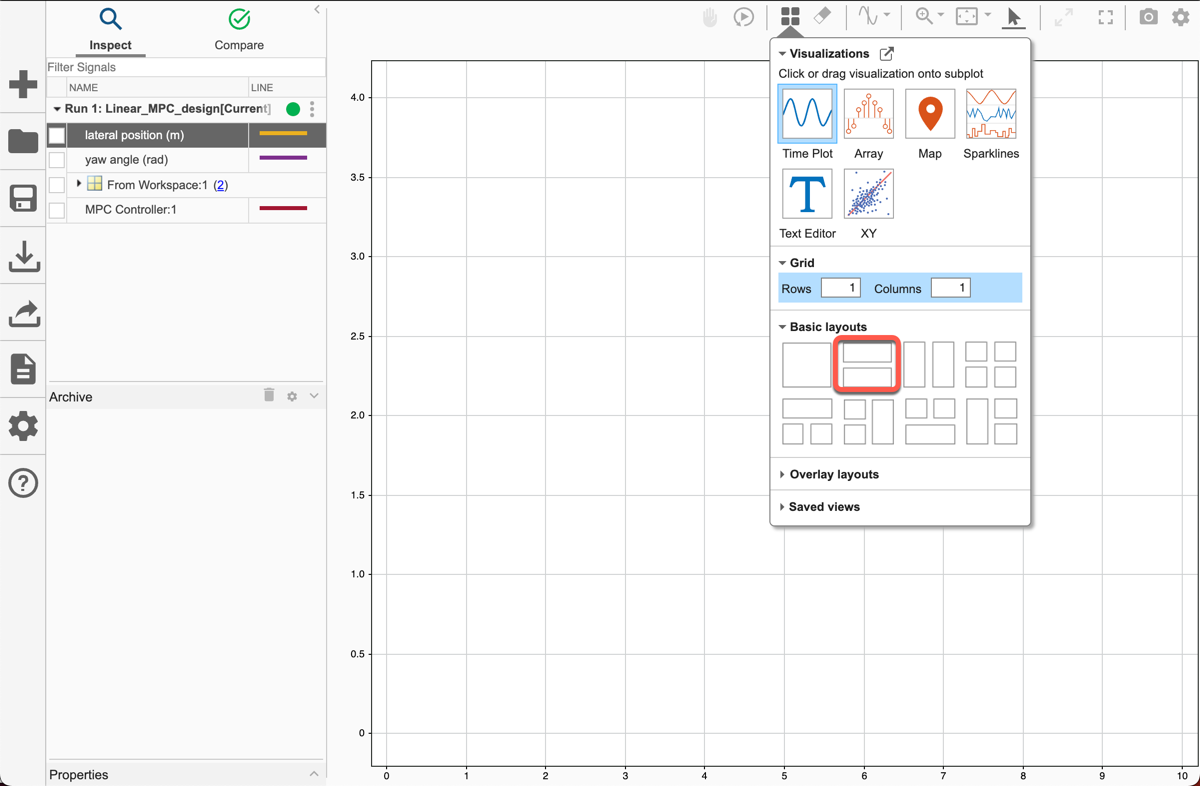

Now, select the top plot, then select the signals for the lateral position from the left side of the app:

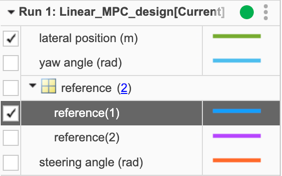

Next, select the bottom plot, then select the signals for the yaw angle from the left side of the app:

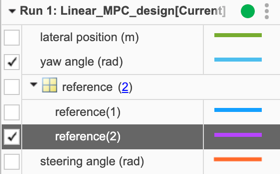

Insert a screenshot below of the plot generated:

{insert here}

**Do the results match with the ones you've observed in the MPC Designer app?**

% task5 = ""

**Task 6. **In this task, you will learn how to tune MPC design parameters such as prediction and control horizons. The prediction horizon is the number of future samples over which the controller tries to minimize the cost. In other words, it defines how far the controller looks into the future. The control horizon is the number of free control moves that the controller uses to minimize the cost over the prediction horizon.

The selection of prediction and control horizons impacts both performance and computational requirements. To test the latter, you will:

- Use the [review](https://www.mathworks.com/help/mpc/ref/mpc.review.html) command to assess the default MPC controller that you designed in **Task 4**, and another controller with larger prediction and control horizons than the default controller as seen in the code below. Once the command is executed, a dialogue will pop up with information about the controller. Select the "Memory Size for MPC Data" test to view the memory requirements for each of the controllers:

 
mpc2 = mpc1;
mpc2.p = 20;
mpc2.c = 15;
review(mpc1);

 
review(mpc2);

- Fill out this table with the results of the review command:

**Task 6a. Discuss below about the differences in memory usage between the controllers:**

% task6a = ""

In this problem, a good place to start in choosing a prediction horizon is to make sure it is long enough to capture the transient response and cover the significant dynamics of the system. So we want to make sure the prediction horizon covers the maneuver time (Prediction Horizon * Sample Time >= Maneuver Time), whose approximate value you computed in **Task 2**. The default controller satisfies this recommendation, however, since a larger prediction horizon increases the computational time of the controller, decrease the prediction horizon to the smallest number that meets this recommendation.

Tune the prediction horizon under the **Tuning** tab in the MPC Designer App. When you update the value, be sure to click on the canvas to update the response plots.

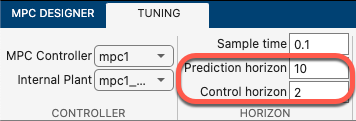

**Task 6b. What values did you try for the prediction horizon and which did you settle on, and why? Insert a screenshot of the scenario results below.**

% task6b = ""

{insert screenshot here}

Now that you have settled on a prediction horizon, you can tune the control horizon. This is the number of future timesteps for which controller action will be optimized and for the remainder of the prediction horizon it will be held constant. 

The first few control actions have a much larger effect on the predicted output, so it is recommended to keep the control horizon much smaller than the prediction horizon in order to reduce computational complexity.

**Task 6c. What value did you choose for the control horizon? Insert a screenshot of the scenario results below.**

% task6c = ""

{insert screenshot here}

**Task 6d. **Export the updated controller to the Simulink model. Return to the Simulink model**,** then press  Play. Press **Observe Vehicle Motion** to run the code below and observe the results.

 
waypoints = [out.simout.time*Vx out.simout.signals(1).values zeros(length(out.simout.signals(1).values),1)];
simulateScenario(simulationTime,waypoints,Vx,150);

Now return to the **Simulation Data Inspector** to observe how the performance has changed with the specified horizons. In the Archive in the bottom left corner, select the signals from **Task 5** to plot alongside the latest run to compare:

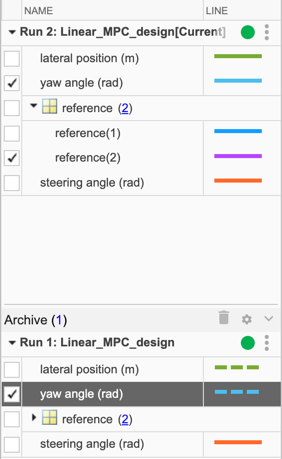

**Note: **Remember to select the plot on the right you would like to plot on before selecting signals. You can change the color/style of the signal by clicking the color next to the signal.

Insert a screenshot below of the plot generated:

{insert here}

**Task 6e. If you were able to further tune the design parameters, you will have achieved improved reference tracking. In the next step, you will specify the design parameters that ensure a comfortable ride for the passenger. What design parameters would contribute to the passenger comfort and how can this be balanced with reference tracking?**

% task6e = ""

**Task 7.** Define constraints and weights in the MPC Designer App. In order to ensure the comfort of the passenger, to enforce the maximum turn radius of the car, and to keep the car within the confines of the road, you will need to define some constraints on the signals. These constraints will be used in the optimization problem solved at each timestep.

In consideration of the comfort of the passenger, you will constrain the maximum steering rate to 15 degrees per second or pi/12 radians in each direction. The car has a limitation on its turn radius, so you will constrain the maximum steering angle to 30 degrees or pi/6 radians in each direction.

In order to ensure the car remains on the road, you will constrain the lateral position to be between -2 and 6 (Diagram provided below).

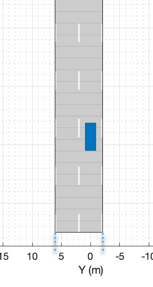 

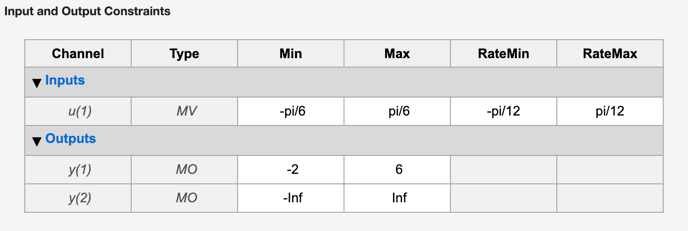

You will also need to assign weights to the Output Variables to prioritize reference tracking of specific variables. Since the primary objective is to track the lateral position, you will assign this a higher weight of 1 while the yaw angle will be assigned 0.1.

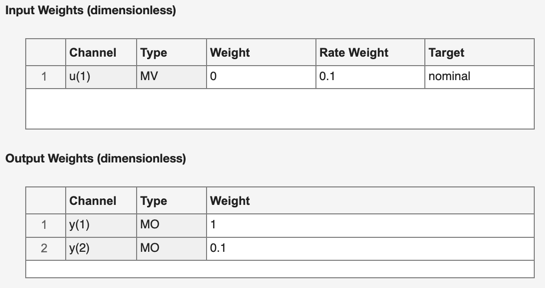

Now that the constraints have been set, you must update the prediction and control horizon. The steering angle rate constraint of 15 deg/s means that it will take an extra second to reach the commanded 30 degree maximum steering angle and the maneuver time will be longer than anticipated above. To account for this, a maneuver time of 1.5 seconds should be used. Update the predictions and control horizon to account for this and insert a screenshot of the response plots in the MPC Designer App below:

{insert here}

Once you are done updating the controller parameters, export the controller back to the model.

Return to the Simulink model**,** then press  Play. You can use the following code to observe the vehicle motion.

 
waypoints = [out.simout.time*Vx out.simout.signals(1).values zeros(length(out.simout.signals(1).values),1)];
simulateScenario(simulationTime,waypoints,Vx,150);

Now return to the **Simulation Data Inspector** to observe how the performance has changed with the constraints and weights. In the Archive in the bottom left corner, select the signals from **Task 6** to plot alongside the latest run to compare.

Insert a screenshot below of the plot generated:

{insert here}

Verify that no constraints are broken, execute the following code that checks that all constraints are met:

 
mv = out.logsout{3}.Values;
lat_pos = out.simout.signals(1).values;
if(max(mv) <= pi/6 && min(mv) >= -pi/6)
    print('Steering Angle within Constraint');
else
    print('Steering Angle Not within Constraint');
end
if(max(mv_dot) <= pi/12 && min(mv_dot) >= -pi/12)
    print('Steering Angle Rate within Constraint');
else
    print('Steering Angle Rate Not within Constraint');
end
if(max(lat_pos) <= 6 && min(lat_pos) >= -2)
    print('Lateral Position within Constraint');
else
    print('Lateral Position Not within Constraint');
end

**How does this compare to the default controller created in Task 5 and the unconstrained controller created in Task 6? Will your passenger be comfortable while also executing a successful lane change?**

% task7 = ""

**Task 8. **In this lab, you designed linear MPCs with the assumption that the longitudinal velocity is constant at 15 m/s. Use the code below to change the velocity to 5 m/s, then rerun the model and use the code below to observe the results. Now, change the velocity to 35 m/s, then rerun and observe the results.

 
Vx = 5;

A = [-(2*Cf+2*Cr)/m/Vx, 0, -Vx-(2*Cf*lf-2*Cr*lr)/m/Vx, 0;
     0, 0, 1, 0;
     -(2*Cf*lf-2*Cr*lr)/Iz/Vx, 0, -(2*Cf*lf^2+2*Cr*lr^2)/Iz/Vx, 0;
     1, Vx, 0, 0];

vehicle = ss(A,B,C,D);

 
waypoints = [out.simout.time*Vx out.simout.signals(1).values zeros(length(out.simout.signals(1).values),1)];
simulateScenario(simulationTime,waypoints,Vx,Vx*out.simout.time(end));

**Comment on how the output changes with varying longitudinal velocity.**

% task8 = ""

## Part 3: Design an adaptive MPC controller for the vehicle steering control system

Previously, it was assumed that the car had a constant longitudinal velocity, so the plant wasn't changing and the state matrix A, was constant. A traditional MPC controller is not effective at handling the varying dynamics as it uses a constant internal plant model. Part 4 of the [video series](https://www.mathworks.com/videos/series/understanding-model-predictive-control.html) discussed that adaptive MPC lets you provide a new linear plant model at each time step as the operating conditions change, therefore it makes more accurate predictions at the new operating conditions. So, to deal with the changing plant dynamics, you can use an adaptive MPC.

**Task 9. **Now that you understand why you may need adaptive MPC, you will learn how to design one:

- To start, open a blank Simulink Model.

- From [Adaptive_Library.slx](matlab:open('./Adaptive_Library.slx')) bring in the **Vehicle**, **Reference**, and **Plant Model Update** blocks to the blank model. The vehicle and reference blocks do the same function as those used in Part 2. The Plant Update Model takes in the states of the vehicle, the vehicle velocity, and the previous control action as inputs to calculate and pass a model of the system to the Adaptive MPC Controller. Use a bus creator to collect the plant model update and connect signals as shown below:

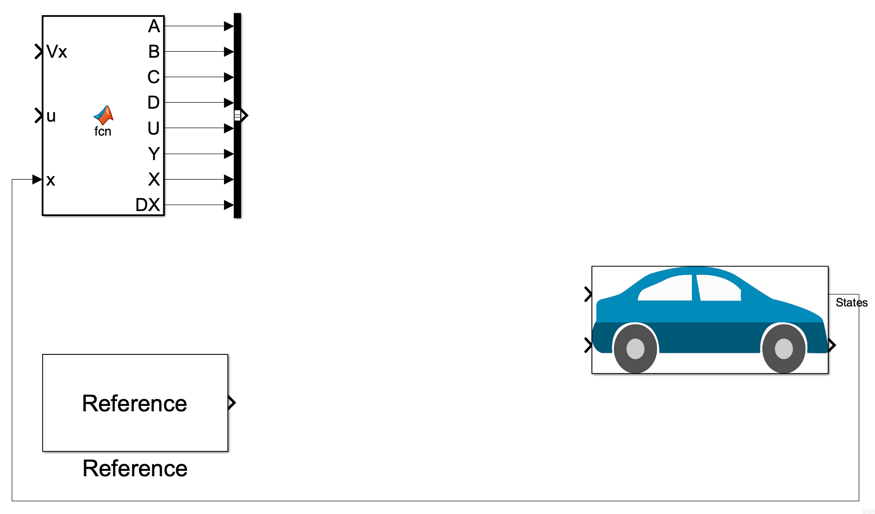

- Next, add a Constant block and Adaptive MPC block and connect as below:

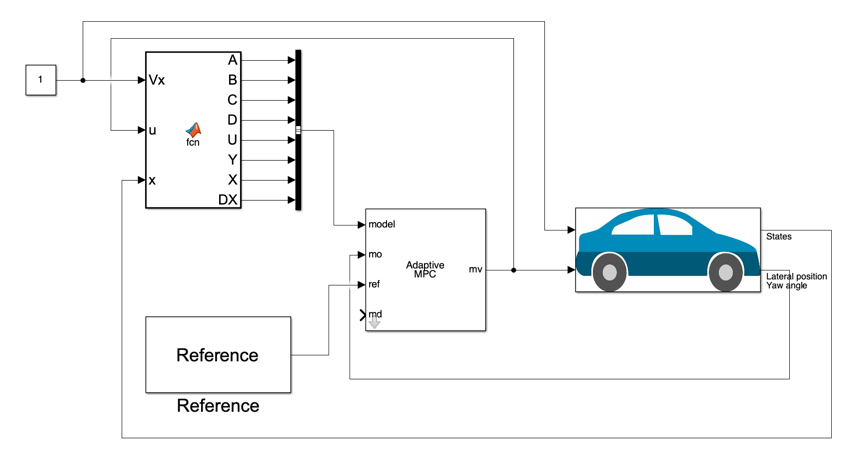

- Double Click to open the Adaptive MPC Parameters and unselect the **Measured Disturbance** inport and add reference to **mpc1**:

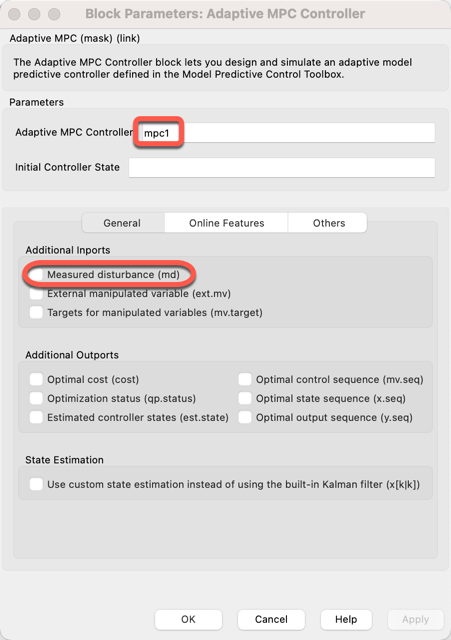

- Then, change the Constant Block Value to 15, this will define the vehicle's longitudinal speed:

- Another important thing to note is that the Plant Model Update block uses the output of the Adaptive MPC Controller as input, and if you are not careful, this will lead to an [algebraic loop](https://www.mathworks.com/help/simulink/ug/algebraic-loops.html). To prevent this, you will need to include a delay of some kind, so that the Plant Model Update uses the input from the previous timestep. Add a [memory](https://www.mathworks.com/help/simulink/slref/memory.html?s_tid=doc_ta) block to the model as below:

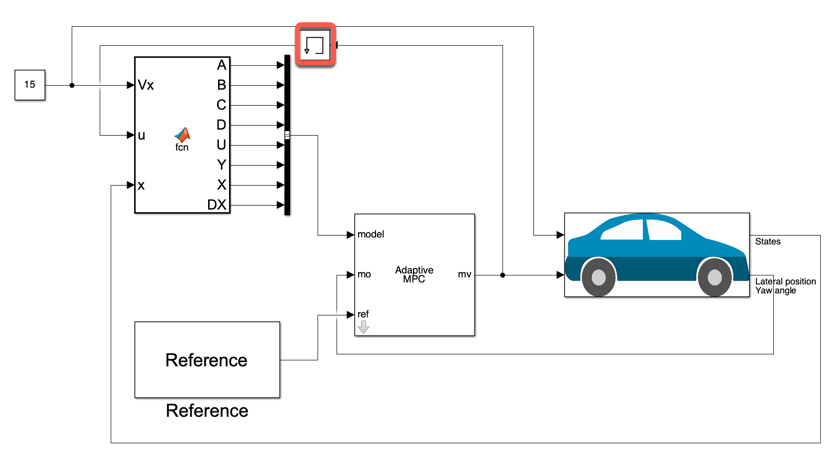

It's important to note that Adaptive MPC requires that the plant model provided to the controller is discrete. Since you have already defined **mpc1,** you can use the [c2d](https://www.mathworks.com/help/ident/ref/dynamicsystem.c2d.html) command to convert the plant from continuous to discrete time in the space below:

%Uncomment the code below and convert the plant to discrete time then use
%the button to run the code
 
% Ts = .1;
% mpc1.Model.Plant = 

**Task 10. **You are now ready to simulate the model, but first you must be able to visualize the output of the model: 

- Add a [Display](https://www.mathworks.com/help/simulink/slref/display.html?s_tid=doc_ta) Block to the model and connect to the **A** matrix output by the Plant Model Update. This will allow you to see how the model of the system dynamics change with the changing values of the longitudinal velocity.

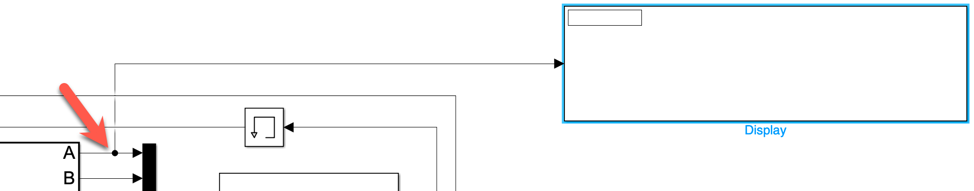

- Now, log the signals as shown below so results can be compared to previous tasks:

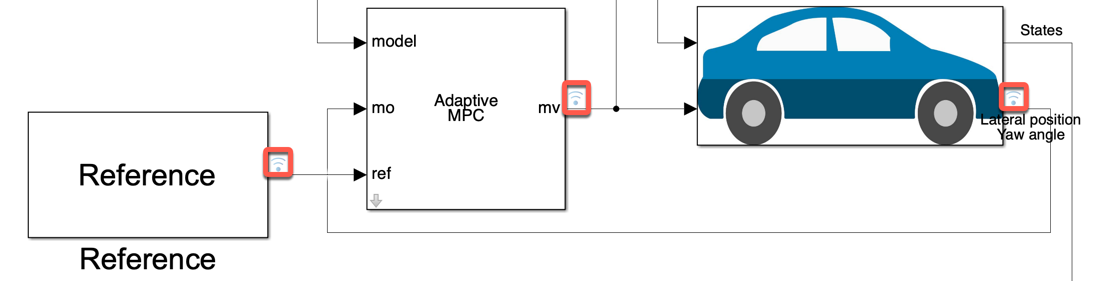

Press  Play and observe how the **A** matrix changes, then insert a screenshot of the results in the **Simulink Data Inspector** below:

{insert here}

**Compare the performance of the adaptive MPC controller for 15 m/s longitudinal velocity with that of the linear MPC in Task 7? Does the controller perform differently at this longitudinal velocity?**

% task10 = ""

**Task 11.** Now, change the Constant block value from 15 to 35 to see how the adaptive MPC performs with a different longitudinal velocity. Press  Play and observe how the **A** matrix changes, then insert a screenshot of the results in the **Simulink Data Inspector** below:

{insert here}

**Compare the performance of the adaptive MPC controller for 35 m/s longitudinal velocity with that of the linear MPC in Task 8? How does the adaptive MPC controller perform differently at this longitudinal velocity?**

% task11 = ""

**Task 12. **Now that you have seen how the Adaptive MPC Controller performs with a different longitudinal velocity, it is time to explore what happens when the velocity is constantly changing throughout the simulation. To simulate this, add a [Sine Wave](https://www.mathworks.com/help/simulink/slref/sinewave.html?s_tid=doc_ta) Block to the model and connect in place of the Constant block. 

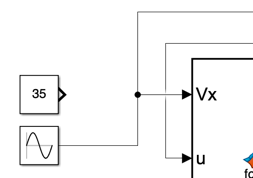

The velocity signal will be oscillating about 35 m/s with an amplitude of 10 meaning that it will vary from 25 m/s to 45 m/s.

Double Click to open the parameters and change them to the following:

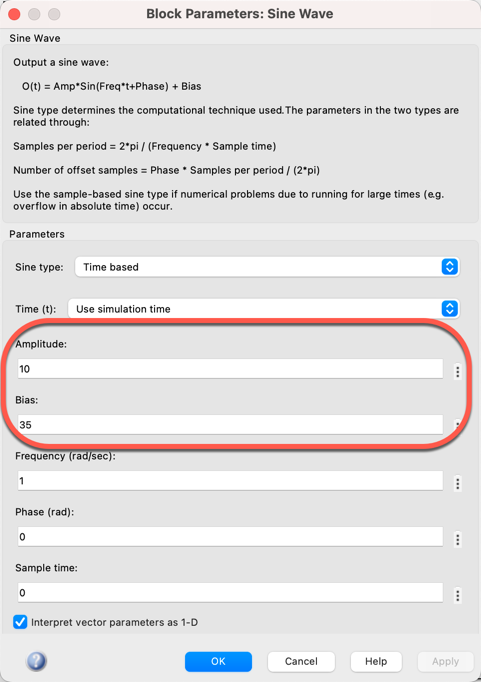

This time, instead of pressing **Play** to run the simulation, use the **Step Forward** button and notice how the** A **matrix changes over time. When you are ready to run the simulation to the end, use the **Continue** button

Then, insert a screenshot of the results in the **Simulink Data Inspector** below:

{insert here}

**How does the controller perform with a variable speed?**

% task12 = ""

## **Bonus Content: Create custom trajectory and/or learn about methods for improved controllers**

**Bonus 1.** Create custom reference trajectory using Driving Scenario Designer app.

Now it's your chance to create your own custom reference trajectory. You will accomplish this with the Driving Scenario Designer from the Automated Driving Toolbox.

 
drivingScenarioDesigner

- Select **Add Road** from Toolstrip

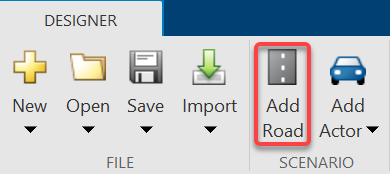

- Draw Road on Canvas, Click to select start and end point then Right Click to exit (don't worry about precision, we will edit further)

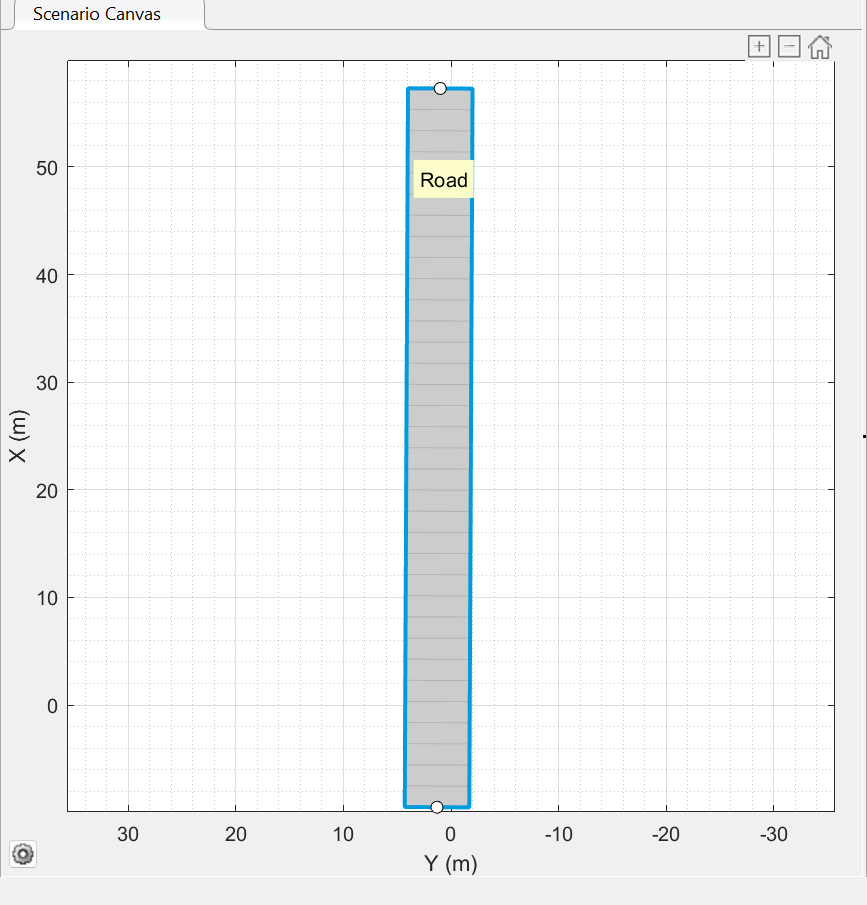

- Open **Lanes** Dropdown, Change number of Lanes to 2. Then update **Road Centers** to following Values: 

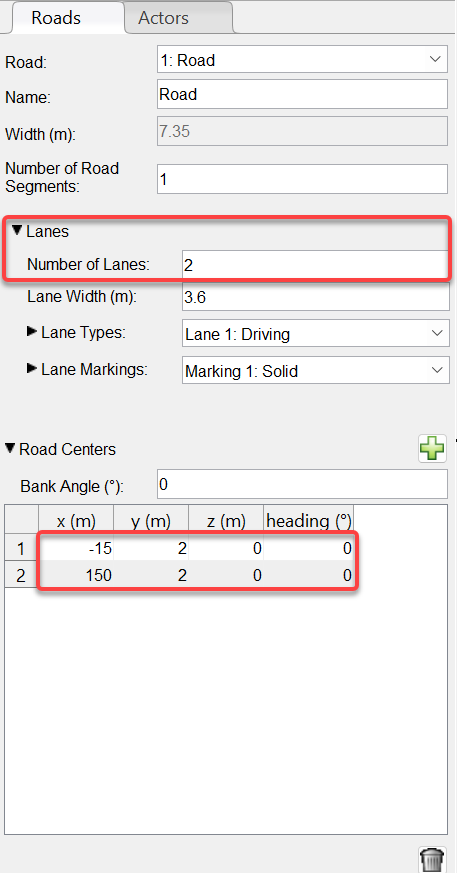

- Select **Add Actor > Car**

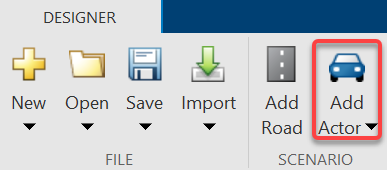

- Click to Place Car (don't worry about precision, we will edit further)

- Open **Trajectory** Dropdown

- Change **Constant Speed** to 15 m/s

- Update **Waypoint 1,** x: -12, y: 0

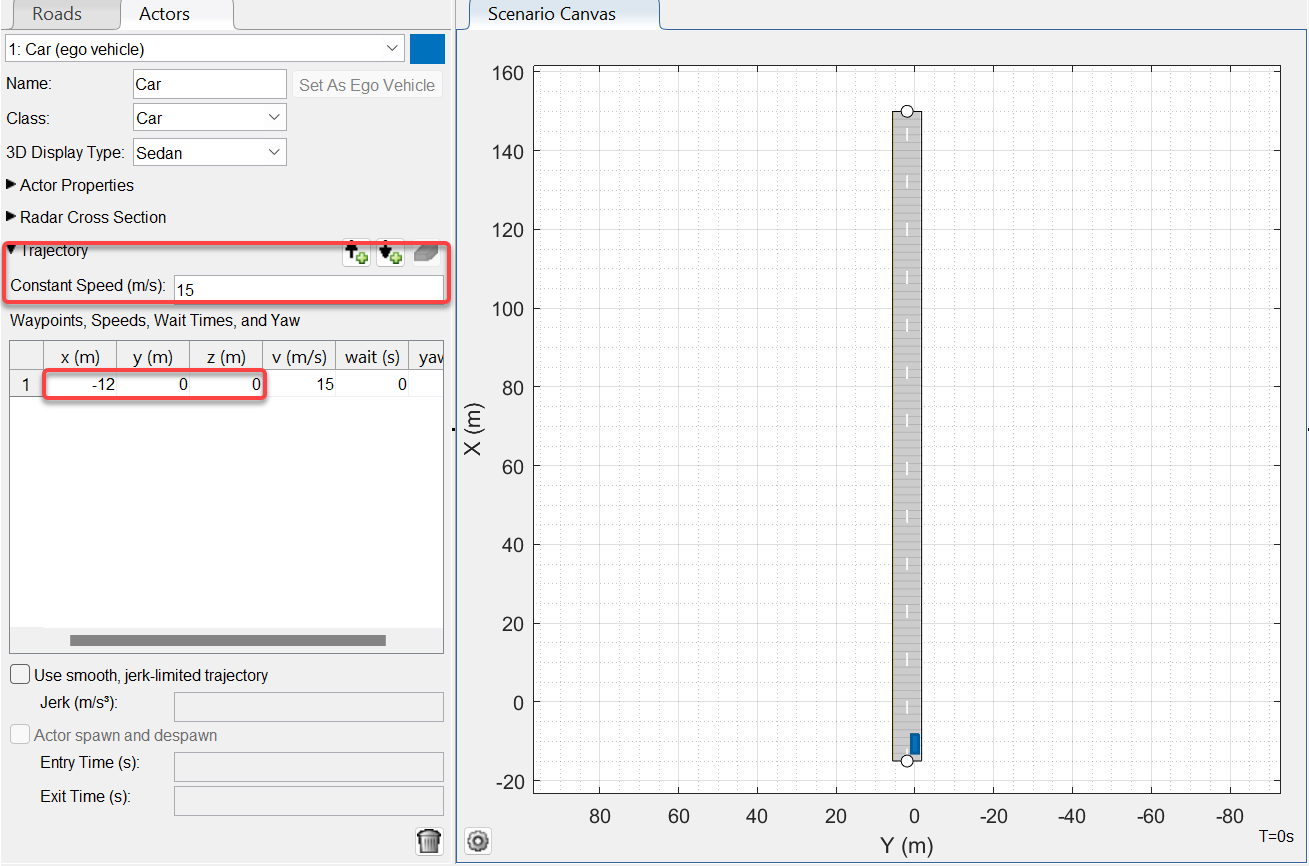

- Select **Add New Forward Waypoint** and Draw Waypoints as desired, Right Click to exit

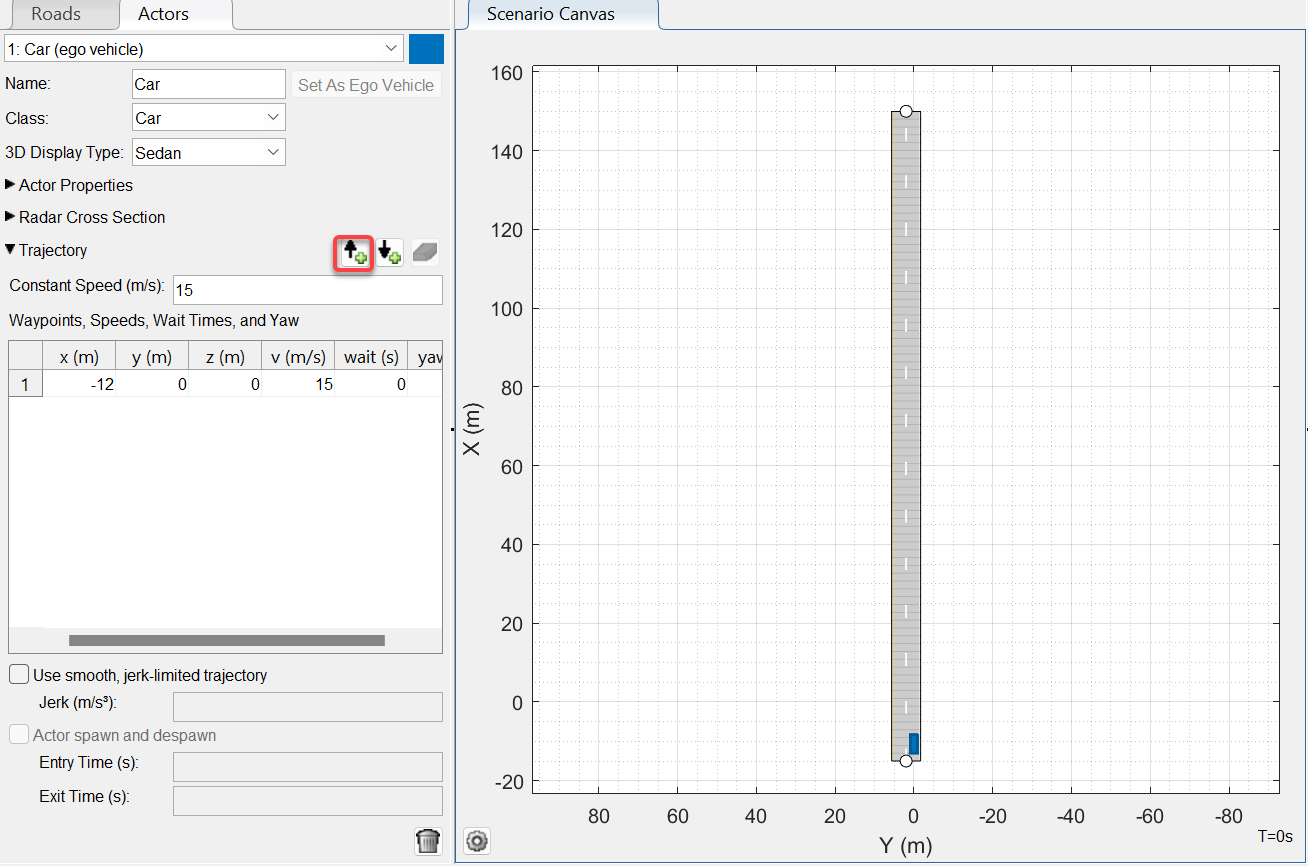

- Select Add Camera from Toolstrip and Place on Front of Car (Sensor type and placement can vary)

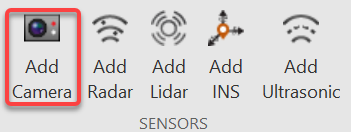

- Export > MATLAB Function

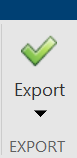

- A function file will open in the editor. Comment out "if isValidTime" and "end" following it on line 35 and 43 respectively so that data is collected at all timesteps, rename function as desired and save the file.

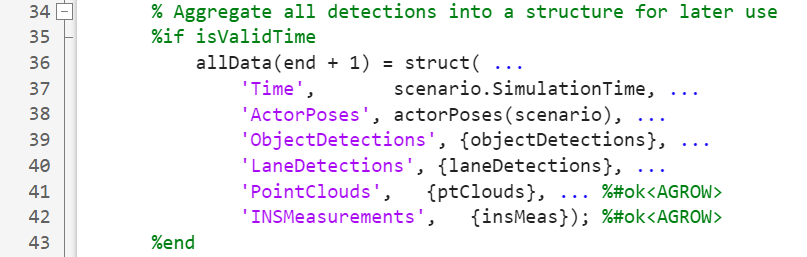

- Run Code Below to generate **reference** variable and verify scenario simulation:

 
% uncomment line below and rename 'yourReferenceName()'
%[allData, scenario, sensor] = yourReferenceName();
t = [allData.Time]';
ap = [allData.ActorPoses];
yawRef = [ap.Yaw]';
posRef = vertcat(ap.Position);
Vx = 15;

simulationTime = 10;
reference = [t posRef(:,2) deg2rad(yawRef)];
waypoints = [t*Vx posRef(:,2) zeros(length(posRef),1)];
simulateScenario(simulationTime,waypoints,Vx); 

Now, you can use the **reference** signal in place of the provided reference in the model from **Part 2 **and/or** Part 3 **and observe how the controller behaves.

**Bonus 2**. Use Preview

Another powerful feature of the MPC block is the ability to preview the reference trajectory a few timesteps ahead of time in order to better optimize the controller**. **To accomplish this, a MATLAB function has been defined that passes the next 7 timesteps of the reference to the MPC Block. This MATLAB Function is located in [Bonus_Library.slx](matlab:open('./Bonus_Library.slx')).

- First, you will need to restore the vehicle dynamics and reference trajectory back to the original values and define sample time Ts for the previewer.

 
Vx = 15;
A = [-(2*Cf+2*Cr)/m/Vx, 0, -Vx-(2*Cf*lf-2*Cr*lr)/m/Vx, 0;
     0, 0, 1, 0;
     -(2*Cf*lf-2*Cr*lr)/Iz/Vx, 0, -(2*Cf*lf^2+2*Cr*lr^2)/Iz/Vx, 0;
     1, Vx, 0, 0];
B = [2*Cf/m 0 2*Cf*lf/Iz 0]';
C = [0 0 0 1; 0 1 0 0];
D = 0;
vehicle = ss(A,B,C,D);

Ts = .1;

- Next, you will replace the reference in the Linear MPC Simulink model you completed in Part 2. To do this, you will add a [Constant](https://www.mathworks.com/help/simulink/slref/constant.html?s_tid=doc_ta) Block with value defined by the reference variable as well as a [Clock](https://www.mathworks.com/help/simulink/slref/clock.html) Block which will serve as inputs to the Previewer. Then, bring in the Previewer [MATLAB Function](https://www.mathworks.com/help/simulink/slref/matlabfunction.html?s_tid=doc_ta) Block from the Bonus_Library.slx. Connect these blocks as shown below:

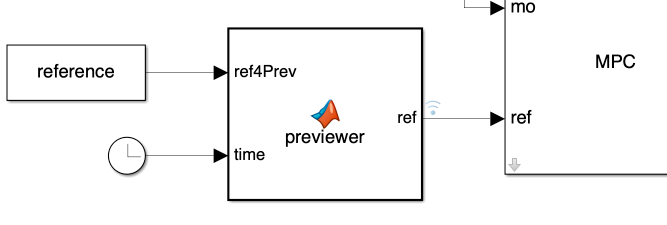

- Finally, since the reference trajectory is completed in shorter than 10 seconds, the previewer block will produce an error with the current simulation Stop Time. To prevent this, change the simulation Stop Time to 5 seconds in the toolstrip at the top of the Simulink Window

      

Now you are ready to run the Simulation. Press  Play and then insert a screenshot of the results below:

{insert here}

**What difference do you observe about the lateral position tracking with and without preview? How does preview help with reference tracking?**

% bonus2 = ''

**Bonus 3**. Lane Keeping Assist Block

Model Predictive Control Toolbox has a built-in block for a Lane Keeping MPC controller**. **In this section, you will learn to use this block to track a reference.

First, you will need to redefine the vehicle dynamics and generate a reference. This example uses a reference that is differentiable, as opposed to the step reference because the Lane Keeping Assist block requires smooth curves. The vehicle LTI System Block will now output not just the Lateral Position and Yaw Angle, but also their rates which will serve as inputs in the Lane Keeping Calculations.

 
Vx = 15;
A = [-(2*Cf+2*Cr)/m/Vx, 0, -Vx-(2*Cf*lf-2*Cr*lr)/m/Vx, 0;
     0, 0, 1, 0;
     -(2*Cf*lf-2*Cr*lr)/Iz/Vx, 0, -(2*Cf*lf^2+2*Cr*lr^2)/Iz/Vx, 0;
     1, Vx, 0, 0];
B = [2*Cf/m 0 2*Cf*lf/Iz 0]';
C = [0 0 0 1; 0 1 0 0; 1 0 0 0; 0 0 1 0];
D = 0;
vehicle = ss(A,B,C,D);

[allData, scenario, sensor] = generateSensorData();
t = [allData.Time]';
ap = [allData.ActorPoses];
yawRef = [ap.Yaw]';
posRef = vertcat(ap.Position);

simulationTime = 10;
reference = [t posRef(:,2) deg2rad(yawRef)];
waypoints = [t*Vx posRef(:,2) zeros(length(posRef),1)];

Next, you will need to use the reference signal to calculate the curvature of the trajectory which will serve as an input to the controller.

 
x = waypoints(:,1);
y = waypoints(:,2);
tq = 0:.001:t(end);
yq = interp1(t,y,tq,'spline')';
xq = interp1(t,x,tq,'spline')';


d1fx = gradient(xq,.001);
d1fy = gradient(yq,.001);
d2fx = gradient(d1fx,.001);
d2fy = gradient(d1fy,.001);

K = d1fx.*d2fy./(d1fx.^2+d1fy.^2).^(3/2);
md.signals.values = K;
md.time = 0:.001:t(end);

Finally, you will bring in the **Curvature Previewer**, **Sensor Dynamics**, and [Lane Keeping Assist System](https://www.mathworks.com/help/mpc/ref/lanekeepingassistsystem.html?s_tid=doc_ta) Blocks from the [Bonus_Library.slx](matlab:open('./Bonus_Library.slx')), as well as a **Constant** Block, connect them in the completed model from **Part 2** as shown below:

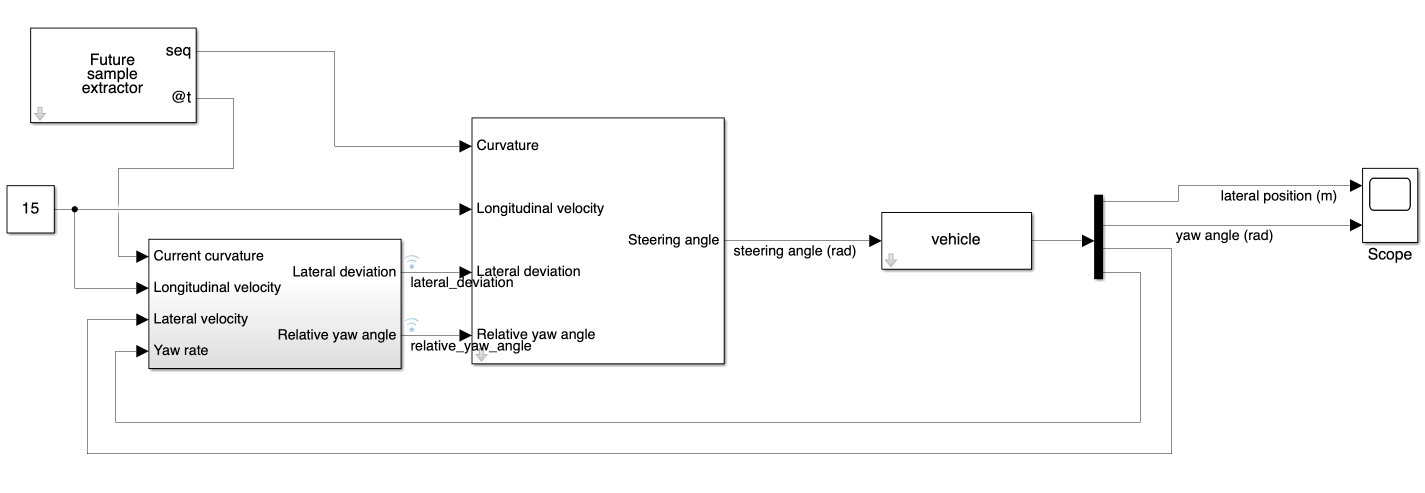

**Note:** that you will need to double click on the **Demux **to change the number of outputs to 4.

Now that you have updated the model, it is time to run the simulation. Press  Play and then insert a screenshot of the results below:

{insert here}

Use the **Run** button to compare the simulation results to the reference:

 
observe(out,reference)

**The Curvature Previewer block lets the Lane Keeping Assist System Block anticipate and account for future changes in the reference so it can proactively adjust its control actions to better handle the upcoming changes. Based on the simulation results, comment on the lateral position and yaw angle tracking accuracy:**

% bonus3 = ''